## Problème 2.1

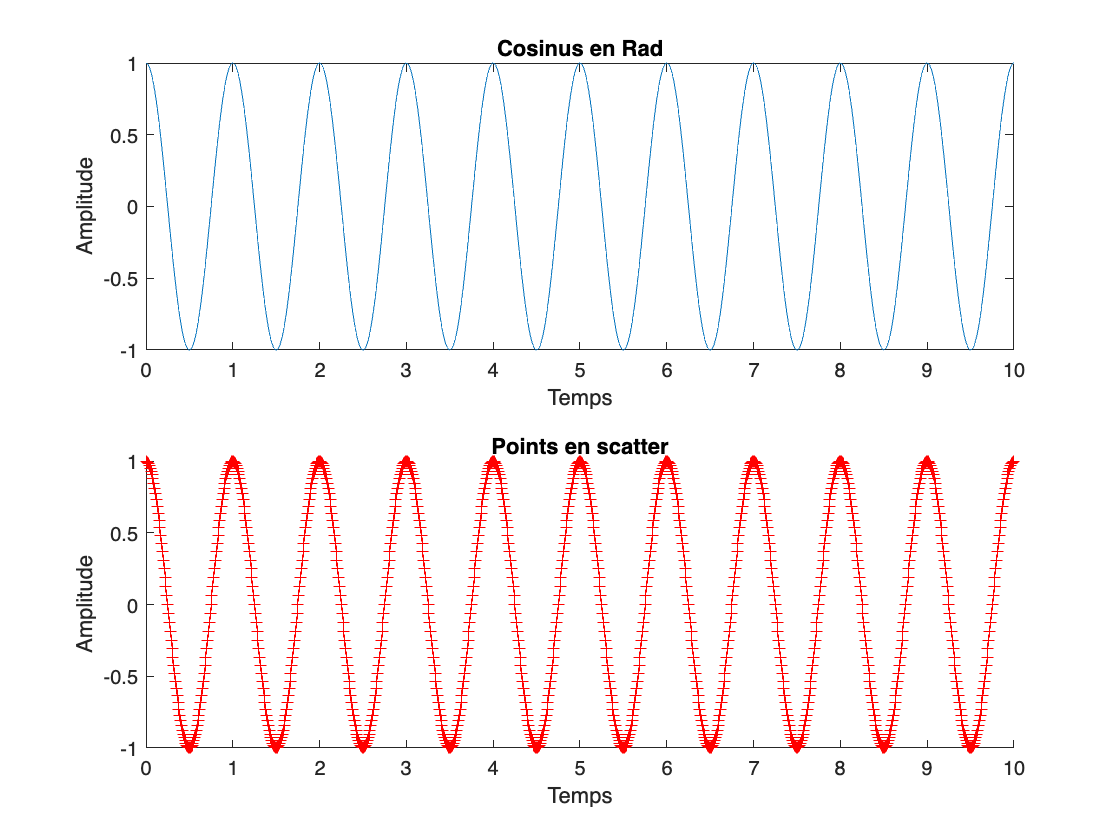

clc
clear
close all

% Fonction pour le temps
dt = 0.01;
t = 0:dt:10;

% Fonction cosinus (Elle prends en radiant)
Y = cos(2*pi*t);

%Fonction cosinus en degré
%Y = cosd(2*t)

%Façon 1 de ploter (Ca fait une ligne)
subplot(2, 1, 1)
plot(t, Y);
title('Cosinus en Rad');
xlabel('Temps');
ylabel('Amplitude');

%Façon 2 de ploter (Ça mets des points partout)
subplot(2, 1, 2)
scatter(t, Y, '+', 'red');
title('Points en scatter');
xlabel('Temps');
ylabel('Amplitude');

## Problème 2.2

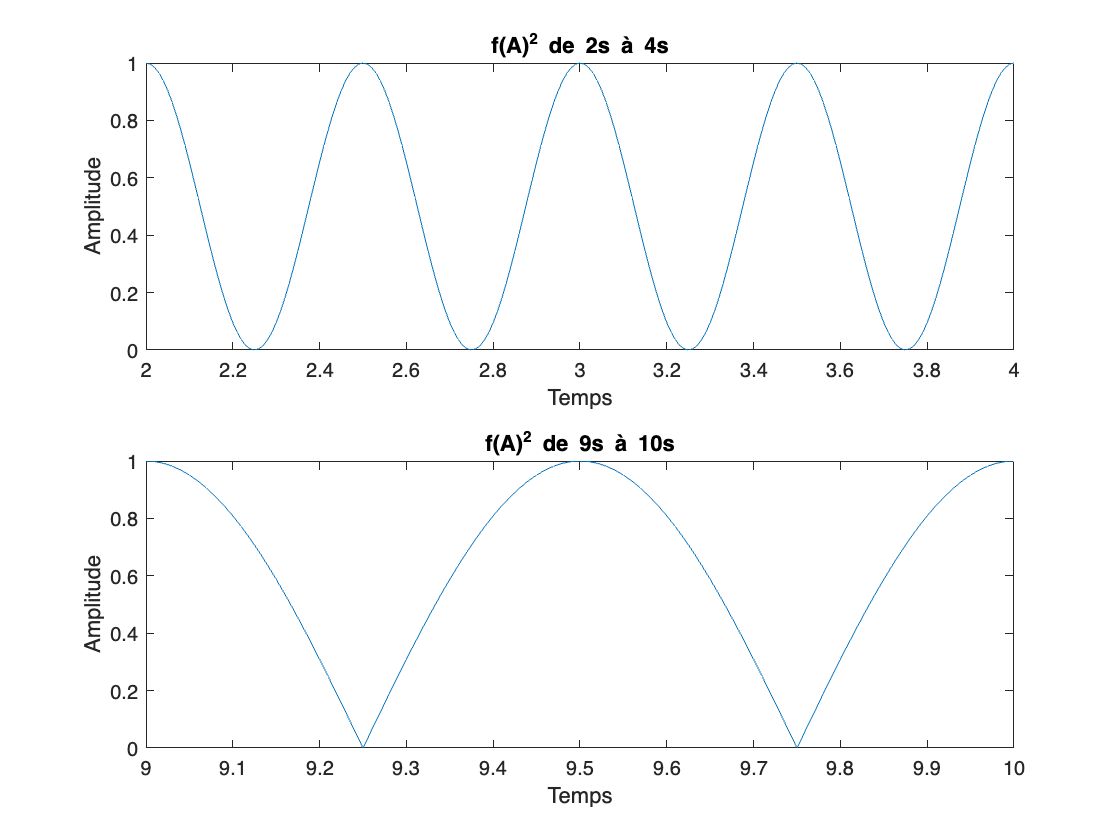

%Juste prendre de 2 à 4
t2 = t(2/dt + 1: 4/dt + 1);
Y2 = cos(2*pi*t2);

%Juste prendre de 9 à 10
t3 = t(9/dt + 1: 10/dt + 1);
Y3 = cos(2*pi*t3);

% .^2 mets au carrer
subplot(2, 1, 1)
plot(t2, Y2.^2);
title('f(A)^2 de 2s à 4s')
xlabel('Temps');
ylabel('Amplitude');

subplot(2, 1, 2)
plot(t3, abs(Y3));
title('f(A)^2 de 9s à 10s')
xlabel('Temps');
ylabel('Amplitude');

## Probleme 2.3

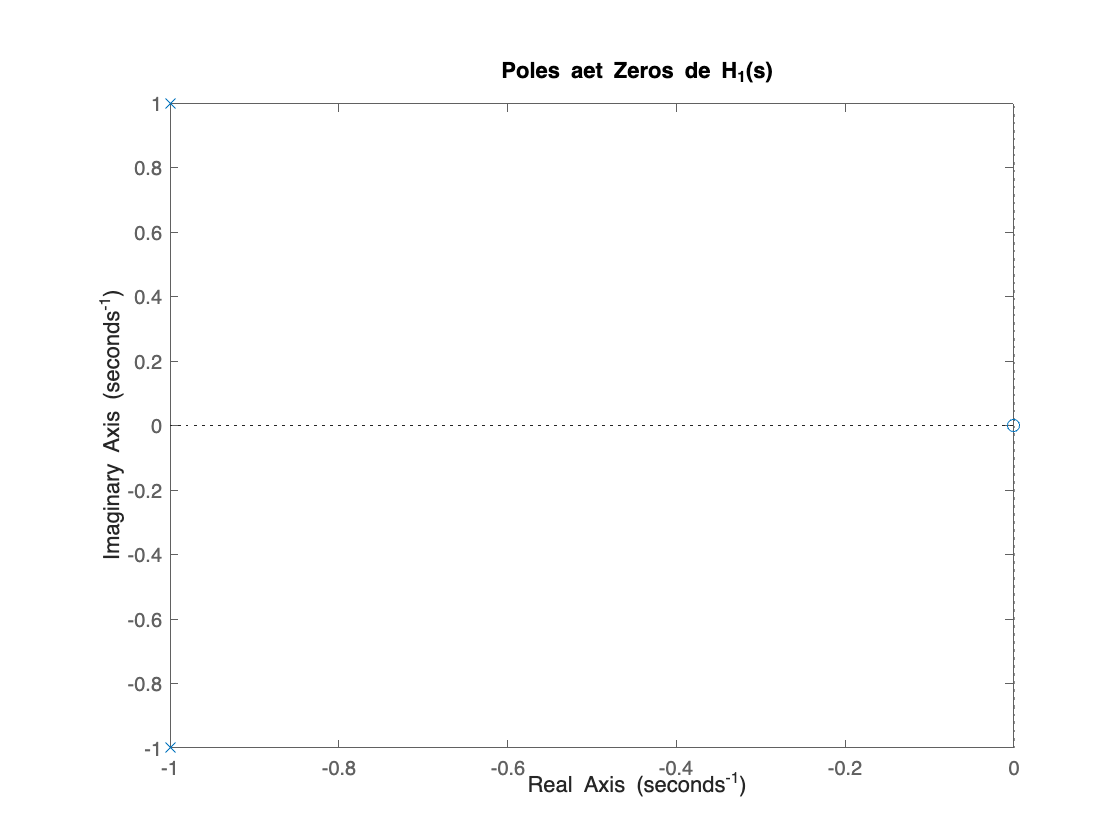

numerateur = [2 0];  % 2s correspond au numérateur
denominateur = [1 2 2];  % s^2 + 2s + 2 corresponds au denominateur
H1 = tf(numerateur, denominateur); % tf c'est transfer function

figure;
pzmap(H1);
title('Poles aet Zeros de H_1(s)');


% Ne pas mettre ; pour que cela affiche
denominateur_roots = roots(denominateur)

denominateur_roots =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


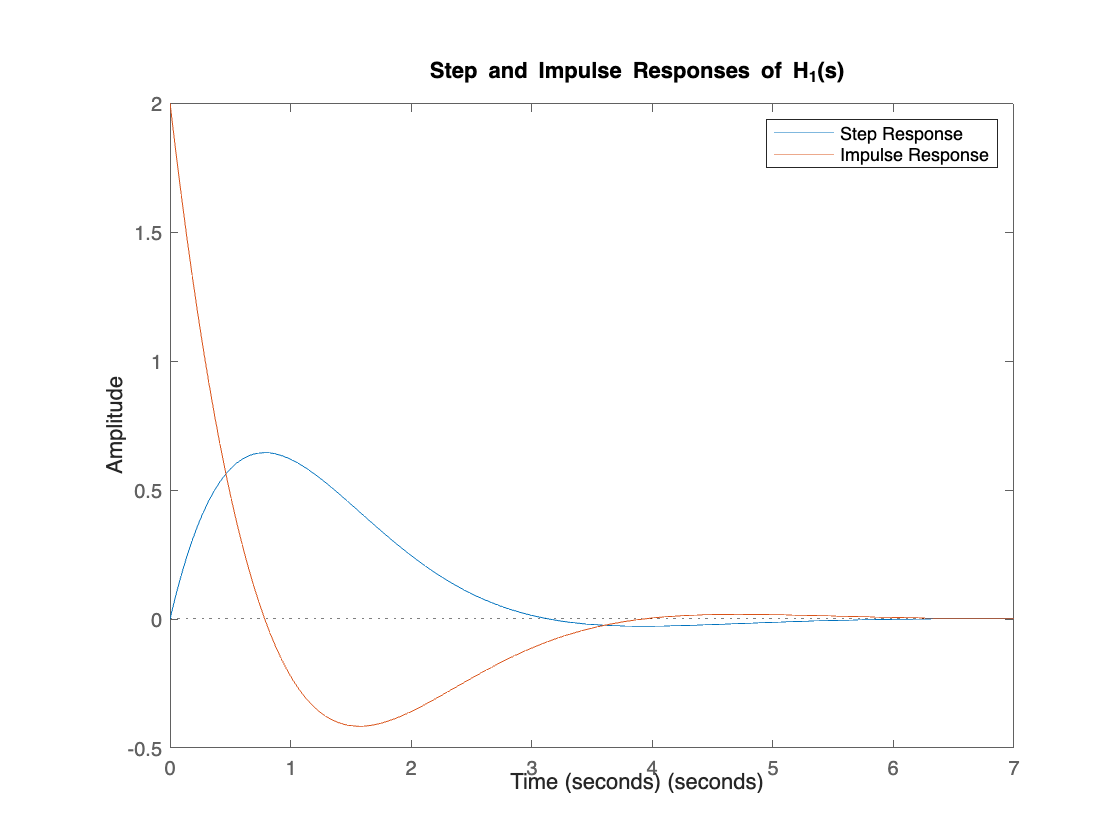


figure;
hold on;
step(H1);  % Step response from 0 to 10 seconds
impulse(H1);  % Impulse response from 0 to 10 seconds
title('Step and Impulse Responses of H_1(s)');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Step Response', 'Impulse Response');
hold off;

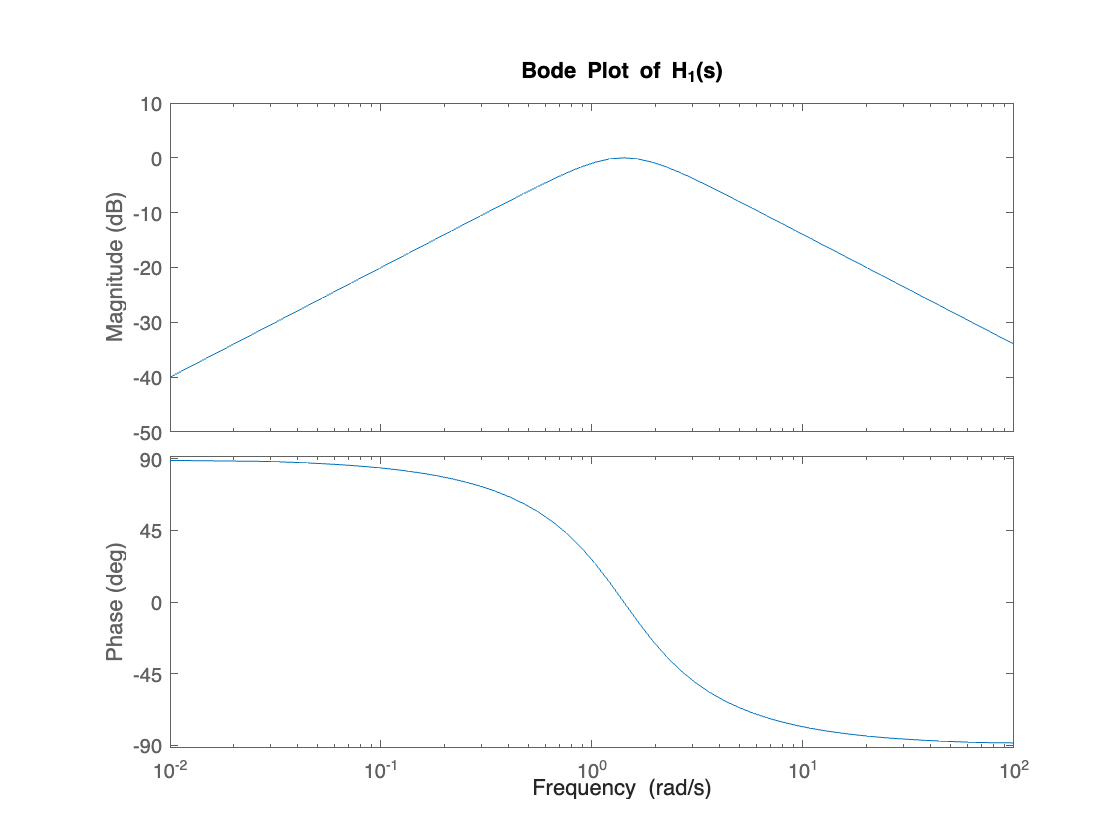


figure;
bode(H1);
title('Bode Plot of H_1(s)');


frequency = 10.3256;  % in Hz
s = 1i * 2 * pi * frequency;  % s = jω where ω = 2πf
H1_s = evalfr(H1, s)

H1_s = 0.0010 - 0.0308i

## Probleme 2.4

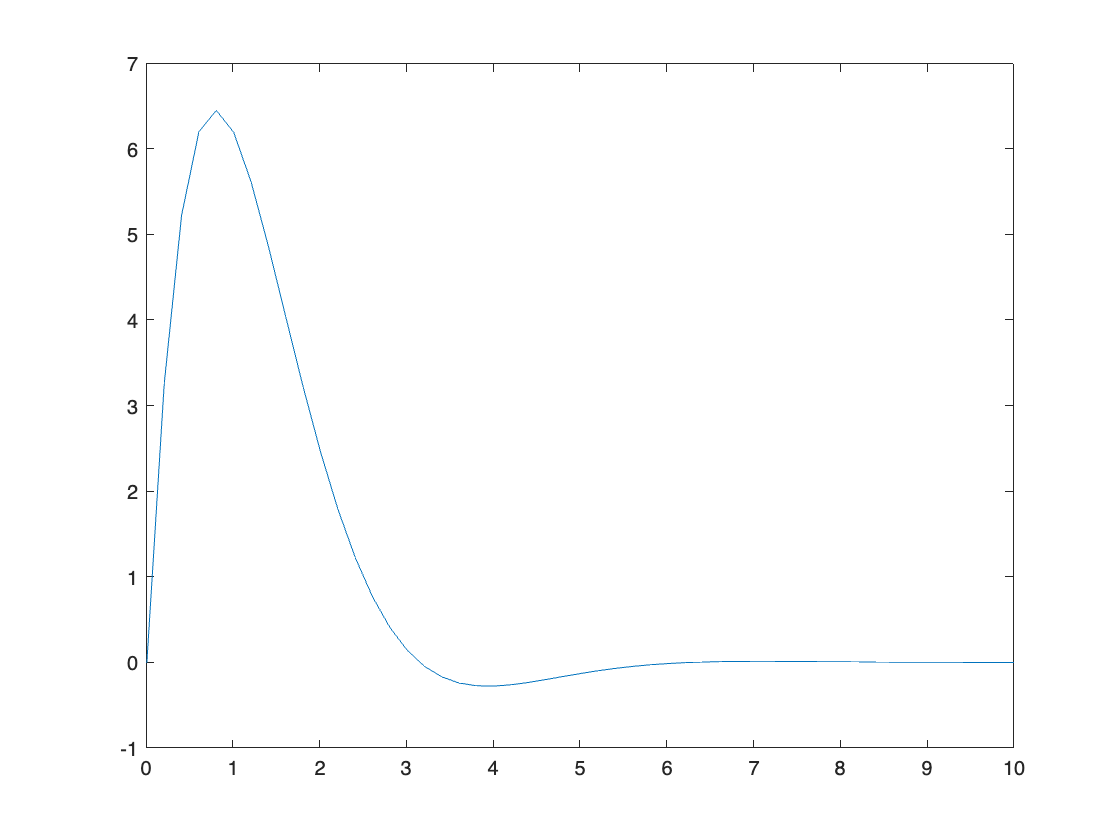

sim('probleme2.mdl');
figure;
plot(out.StepResponse.Time, out.StepResponse.Data)